% load data
clear
load('Assignment_Data_SC42145.mat');
G = tf(FWT(1:2,1:2));

% build Performance Weight matrices
Wp11 = tf([1/1.8, 0.8*pi], [1, 0.8*pi*1e-4]);
Wu22 = tf([5e-3, 7e-4, 5e-5], [1, 14e-4, 1e-6]);

Wp = [Wp11 0; 0 0.2];
Wu = [0.01 0; 0 Wu22];

% build Uncertainty Weight matrices
Wi1 = tf([1/(16*pi), 0.3], [1/(64*pi), 1]);
Wi2 = Wi1;
Wo1 = tf([0.05, 0.2], [0.01, 1]);
Wo2 = Wo1;

Wi = blkdiag(Wi1, Wi2);
Wo = blkdiag(Wo1, Wo2);
Wi.InputName = {'u_1d1'; 'u_1d2'};
Wi.OutputName = {'y_1d1'; 'y_1d2'};

Wo.InputName = {'u_2d1'; 'u_2d2'};
Wo.OutputName = {'y_2d1';'y_2d2'};


Delta = blkdiag(ultidyn('D_i1',[1,1], 'bound',1), ultidyn('D_i2',[1,1], 'bound',1),...
                ultidyn('D_o1',[1,1], 'bound',1),ultidyn('D_o2',[1,1], 'bound',1));
Delta.OutputName = {'u_1d1'; 'u_1d2'; 'u_2d1'; 'u_2d2';};
Delta.InputName = {'y_1d1'; 'y_1d2'; 'y_2d1';'y_2d2'};

P11=[Wp; zeros(2,2)]; P12=[Wp*G; Wu]; P21=eye(2); P22=G;
P = [P11 P12; P21 P22];
P.OutputName = {'z_11'; 'z_12';'z_21'; 'z_22';'v_1';'v_2'};
P.InputName = {'w_1'; 'w_2'; 'u_1'; 'u_2'};


## Connect to plant

 
 
 
Iteration Number:  1
--------------------
 

  Test bounds:  0.79 <=  gamma  <=  2.4

   gamma       X>=0        Y>=0       rho(XY)<1    p/f
  1.4e+00     0.0e+00     0.0e+00     0.000e+00     p
  Limiting gains...
  1.4e+00     0.0e+00     0.0e+00     2.170e-14     p

  Best performance (actual): 1.1
Calculating MU of closed-loop system:
Points completed: 150/150
Iteration Summary            
-----------------------------
Iteration #                 1
Controller Order           30
Total D-Scale Order         0
Gamma Acheived          1.091
Peak mu-Value           1.055
 
Auto Fit in Progress 
	 Block 1, MaxOrder=5, Order = 0
 
 
 
Iteration Number:  2
--------------------
 

  Test bounds:  0.794 <=  gamma  <=  1.21

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  9.81e-01     0.0e+00     0.0e+00     0.000e+00     p
  8.83e-01     0.0e+00     0.0e+00     0.000e+00     p
  8.37e-01     0.0e+00     0.0e+00     0.000e+00     p
  8.15e-01     0.0e+00     0.0e+00     0.000e

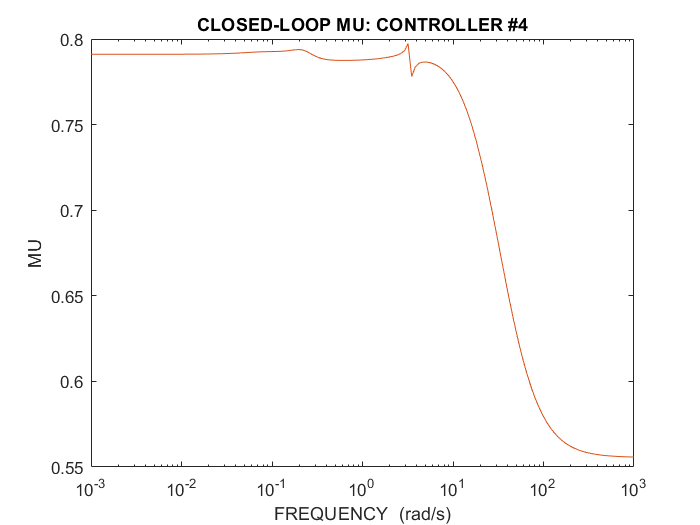

Iteration Summary                                          
-----------------------------------------------------------
Iteration #                 1         2         3         4
Controller Order           30        30        30        30
Total D-Scale Order         0         0         0         0
Gamma Acheived          1.091     0.799     0.799     0.799
Peak mu-Value           1.055     0.797     0.797     0.797
 
 Next MU iteration number:  5




% connect Wo
P_out = {'y_2d1';'y_2d2';'z_11'; 'z_12';'z_21'; 'z_22';'v_1';'v_2'};
P_in = {'u_2d1'; 'u_2d2'; 'w_1'; 'w_2'; 'u_1'; 'u_2'};
P_ = connect(P,Wo, P_in, P_out);

% connect Wi
P_out = {'y_1d1'; 'y_1d2'; 'y_2d1';'y_2d2';'z_11'; 'z_12';'z_21'; 'z_22';'v_1';'v_2'};
P_in = {'u_1d1'; 'u_1d2'; 'u_2d1'; 'u_2d2'; 'w_1'; 'w_2'; 'u_1'; 'u_2'};
P_ = connect(P_,Wi, P_in, P_out);

% connect Delta
Punc = connect(Delta, P_, {'w_1'; 'w_2'; 'u_1'; 'u_2'} ,{'z_11'; 'z_12'; 'z_21'; 'z_22'; 'v_1'; 'v_2'});
% [K,clp,dkinfo] = musyn(Punc,2,2);
omega = logspace(-3,3,150);
opt = dkitopt('FrequencyVector', omega, 'DisplayWhileAutoIter', 'on');
[K,clp,dkinfo] = dksyn(Punc,2,2, opt);

K.InputName = {'v_1';'v_2'};
K.OutputName = {'u_1'; 'u_2'};
N_inputnames = {'u_1d1'; 'u_1d2'; 'u_2d1'; 'u_2d2'; 'w_1'; 'w_2';};
N_outputnames = {'y_1d1'; 'y_1d2'; 'y_2d1';'y_2d2';'z_11'; 'z_12';'z_21'; 'z_22'};

tf_y_v = 1;
N = connect(P_,tf_y_v*K, N_inputnames, N_outputnames);
%M = lft(D, N);

evalN(N)

Nominal stability: true (-0.000251) 
Points completed: 150/150
Nominal performance: true (0.797331) 
Points completed: 150/150
Robust stability: false (4.975228) 
Points completed: 150/150
Robust performance: false (4.975228) 
